Generate initial Gold sequence (simulated Tx).

goldseqA = comm.GoldSequence('FirstPolynomial','x^5+x^2+1',...
    'SecondPolynomial','x^5+x^4+x^3+x^2+1',...
    'FirstInitialConditions',[1 0 1 0 1],...
    'SecondInitialConditions',[0 1 0 1 0],...
    'Index',4,'SamplesPerFrame',60);

Generate a second sequence (simulated Rx). This sequence should have the same parameters.

goldseqB = comm.GoldSequence('FirstPolynomial','x^5+x^2+1',...
    'SecondPolynomial','x^5+x^4+x^3+x^2+1',...
    'FirstInitialConditions',[1 0 1 0 1],...
    'SecondInitialConditions',[0 1 0 1 0],...
    'Index',4,'SamplesPerFrame',60);

Calculate cross-correlation of the 2 signals. Plot the the result and calculate the maximum cross correlation value.

*TODO: la gráfica debería estar centrada en "Samples per frame" y negativos por un lado y positivos por otro. A lo mejor será preferible usar plot en vez de stem.*

y = xcorr(goldseqA(),goldseqB())

y =     1.0000
    2.0000
    2.0000
    1.0000
    1.0000
    2.0000
    1.0000
    1.0000
    1.0000
    0.0000


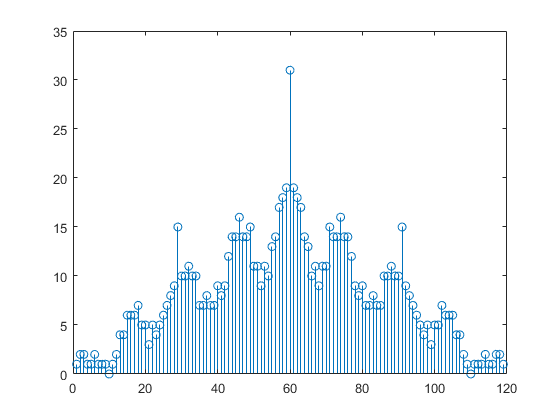

stem(y)

[maxVal,maxPos] = max(y)

maxVal = 31

maxPos = 60

Introduce some delay to check the feasibility of the algorithm.

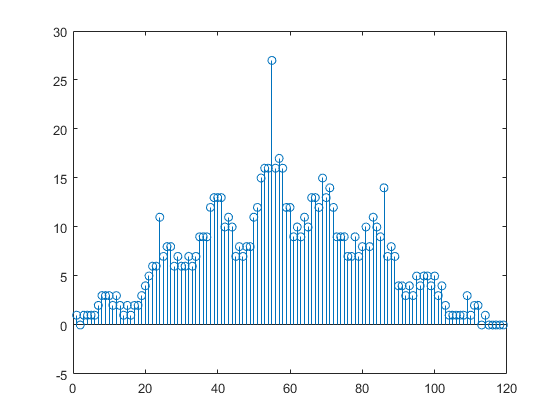

delay = dsp.Delay(5);
delayedGoldSeqB = delay(goldseqB());

y = xcorr(goldseqA(),delayedGoldSeqB);
stem(y)

[maxVal,maxPos] = max(y)

maxVal = 27

maxPos = 55

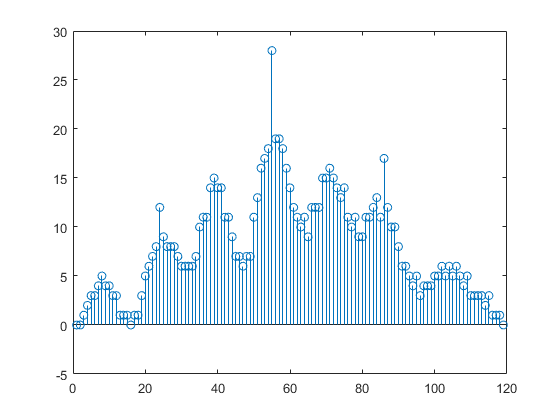

shiftedGoldSeqB = circshift(goldseqB(),5);
y = xcorr(goldseqA(),shiftedGoldSeqB);
stem(y)

[maxVal,maxPos] = max(y)

maxVal = 28

maxPos = 55